# Configuração do FM para análise de Banda

## Configura modulador

Kf = 10;
wc = 40*pi;
wm = 2*pi;
Ap = 2*pi

Ap = 6.2832

## Análise temporal

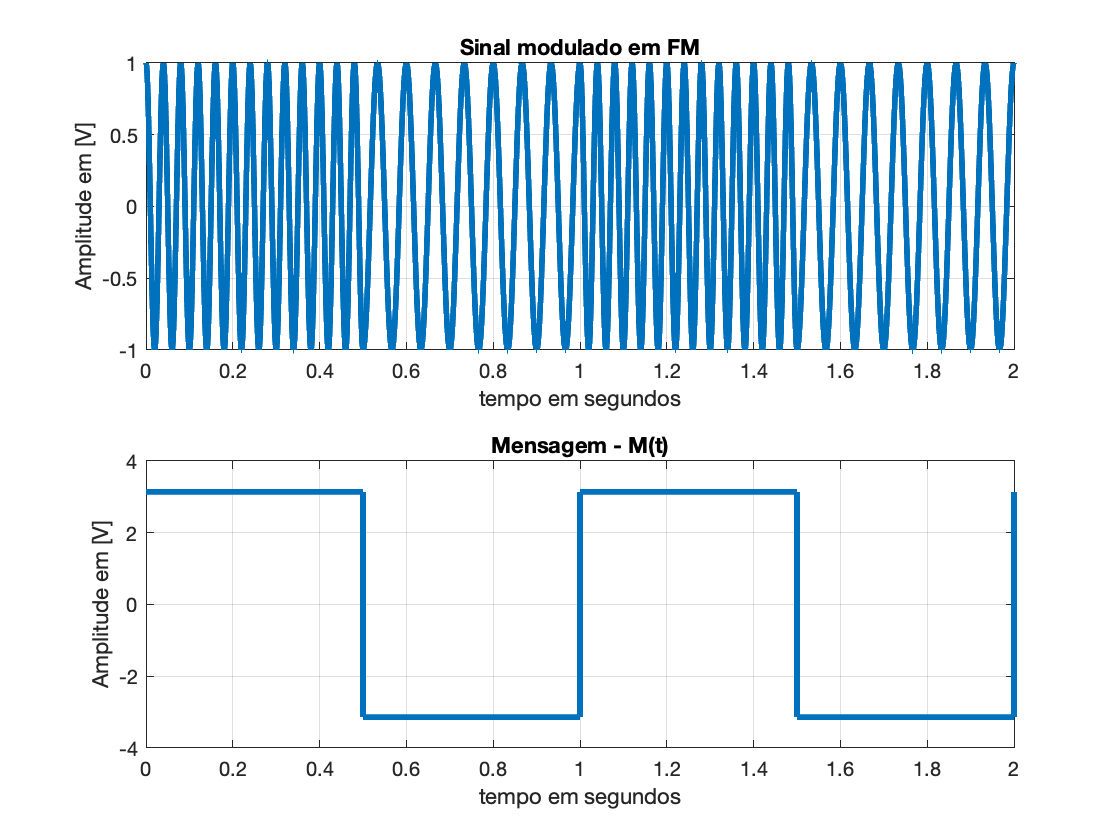

M = out.Mensagem;
FM = out.FM;
tempo =  out.tout;

figure(1)

subplot(2,1,1)

plot(tempo,FM,'LineWidth',3);
title('Sinal modulado em FM');
ylabel('Amplitude em [V]');
xlabel('tempo em segundos');
grid;

subplot(2,1,2)

plot(tempo,M,'LineWidth',3);
title('Mensagem - M(t)');
ylabel('Amplitude em [V]');
xlabel('tempo em segundos');
grid;

## Análise espectral

%%% acertando o eixo frequência

NP = length(tempo);     % número de pontos
Ts = tempo(end)/NP;     % tempo de amostragem
fs = 1/Ts;              % frequência de amostragem

f  = linspace(-fs/2,fs/2,NP)    % eixo frequência

f = 	1.0e+03 *

   -5.0042   -5.0037   -5.0032   -5.0027   -5.0022   -5.0017   -5.0012   -5.0007   -5.0002   -4.9997   -4.9992   -4.9987   -4.9982   -4.9977   -4.9972   -4.9967   -4.9962   -4.9957   -4.9952   -4.9947   -4.9942   -4.9937   -4.9932   -4.9927   -4.9922   -4.9917   -4.9912   -4.9907   -4.9902   -4.9897   -4.9892   -4.9887   -4.9882   -4.9877   -4.9872   -4.9867   -4.9862   -4.9857   -4.9852   -4.9847   -4.9842   -4.9837   -4.9832   -4.9827   -4.9822   -4.9817   -4.9812   -4.9807   -4.9802   -4.9797



Mw = fft(M/(max(M)));
FMw = fft(FM)

FMw = 	1.0e+03 *

   0.0136 + 0.0000i
  -0.0110 - 0.0004i
   0.0171 + 0.0000i
  -0.0111 + 0.0004i
   0.0138 - 0.0371i
  -0.0112 - 0.0005i
   0.0175 + 0.0000i
  -0.0114 + 0.0006i
   0.0145 - 0.0799i
  -0.0118 - 0.0008i


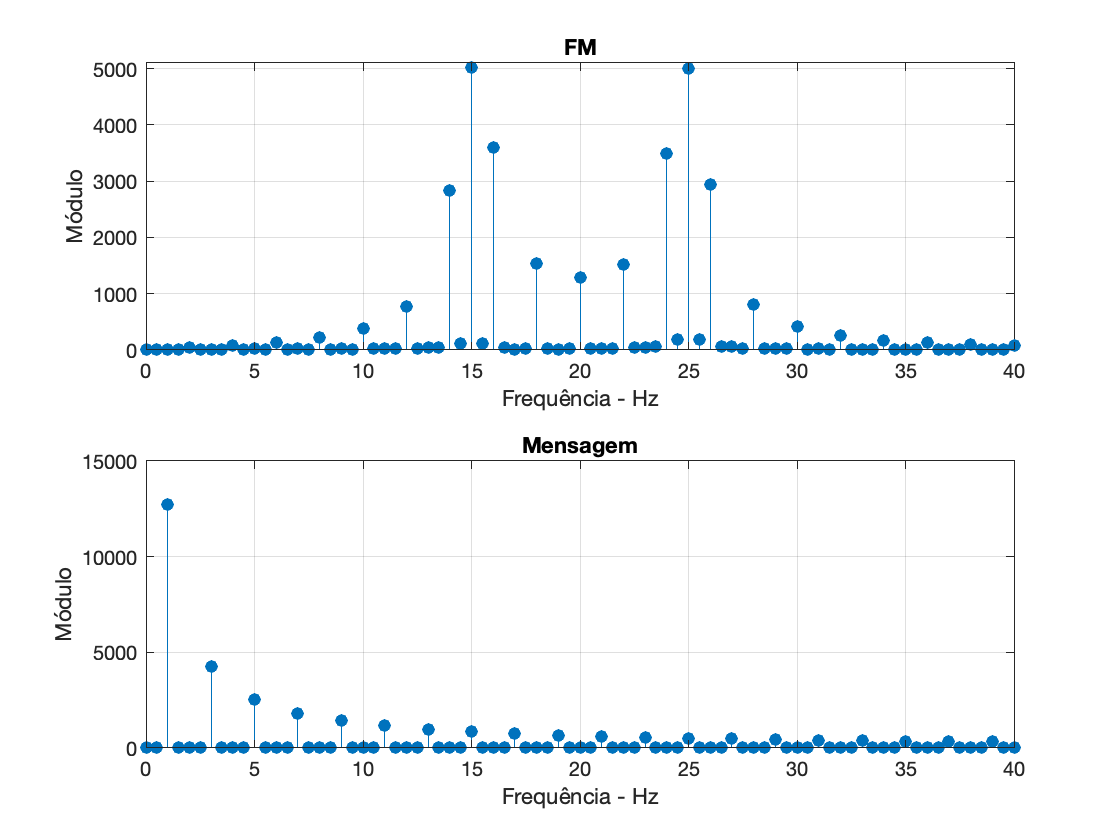


subplot(2,1,1)
stem(f,fftshift(abs(FMw)),'filled')
title('FM')
xlabel('Frequência - Hz')
ylabel('Módulo')
xlim([0 40])
ylim([0 5100])
grid


subplot(2,1,2)
stem(f,fftshift(abs(Mw)),'filled')
title('Mensagem')
xlabel('Frequência - Hz')
ylabel('Módulo')
xlim([0 40])
ylim([0 15000])
grid